# Design Cooling System 

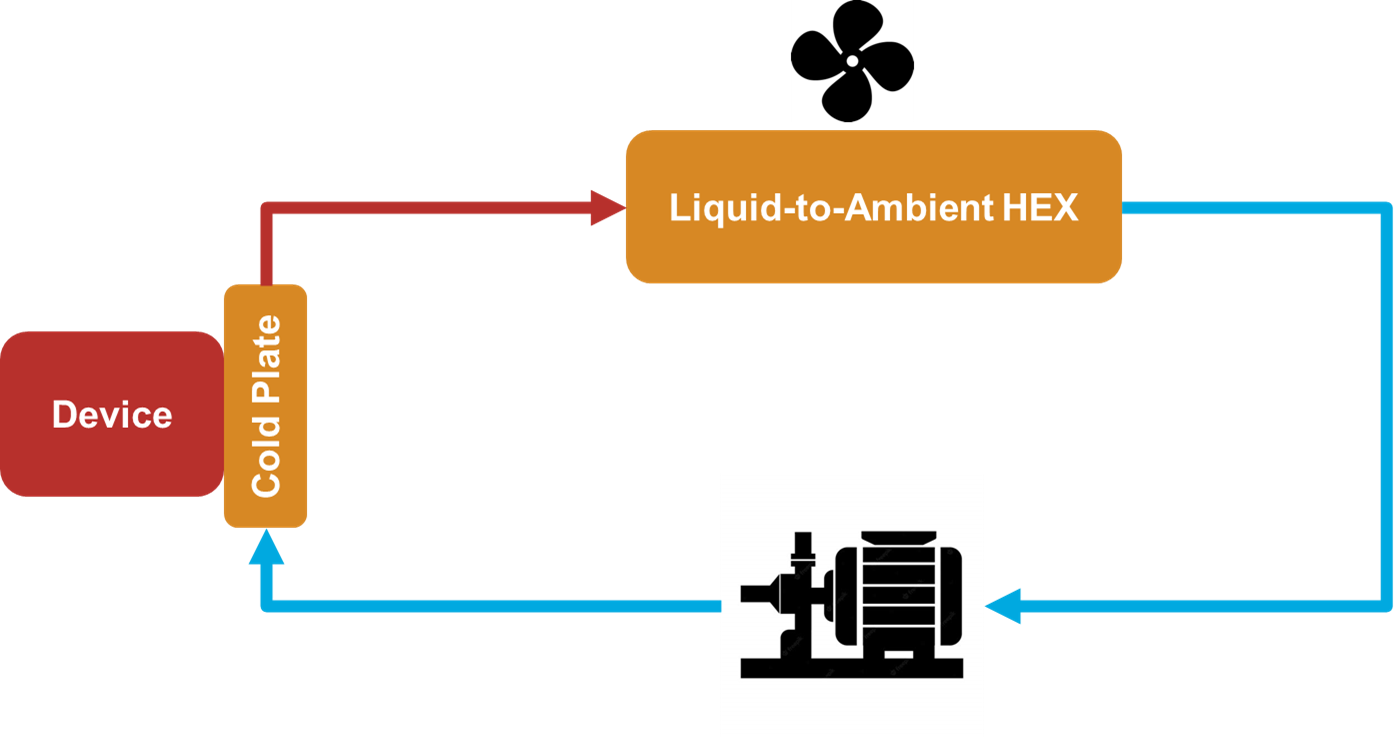

### Requirements for X-Ray Tube Cooling

- Remove a maximum of 2 kW 

- Allowed coolant temperature rise 5°C

- Temperature set point: 25°C

- Device temperature should not exceed 50°C

- Working fluid: Water

- Working fluid pressurized at 2 bar

- Temperature stability +/- n°C

- Operating conditions: Inside at room temperature at 20°C 

#### Sizing and testing the cooling loop components 

The steps to parameterize and build the components in Simscape are organized into specific scripts:

- [Cold Plate](matlab:open('.\ColdPlate.mlx'))

- [Radiator](matlab:open('.\Radiator.mlx'))

- [Pump](matlab:open('.\Pump.mlx'))

#### Assembling and testing the cooling loop components - Open loop

We start the assembly of the overall system, by connecting them in an open loop fashion. 

For better reuse the individual components have been put into Subsystem References:

open_system("ColdPlateSubsystem")
open_system("RadiatorSubsystem")
open_system("PipingSubsystem")
open_system("PumpSubsystem")

Note that the pump model has configured the pump rotational velocity as an input, so it can in a next step be connected to a test input and further to the output of the control. Also, the pump inertia's *Rotational velocity* initial value is set to a *Priority* of *None, *since this will directly be connected to a velocity input. Similarly, the heat input to the device mass and cold plate is configured to receive an external input from a Simulink signal, so we can later define different operating scenarios. 

All Subsystem References are connected into one model thet test input into the pump is a step functions which steps up to the pumps reference speed to create the desired flow for a maximum heat load. The system is intialized at a pressurized at 2 bar, and at the desired coolant inlet temperature of 25°C. 

pumpInpSpeed = 2900; % rpm
open_system("example_System_Assembly")   

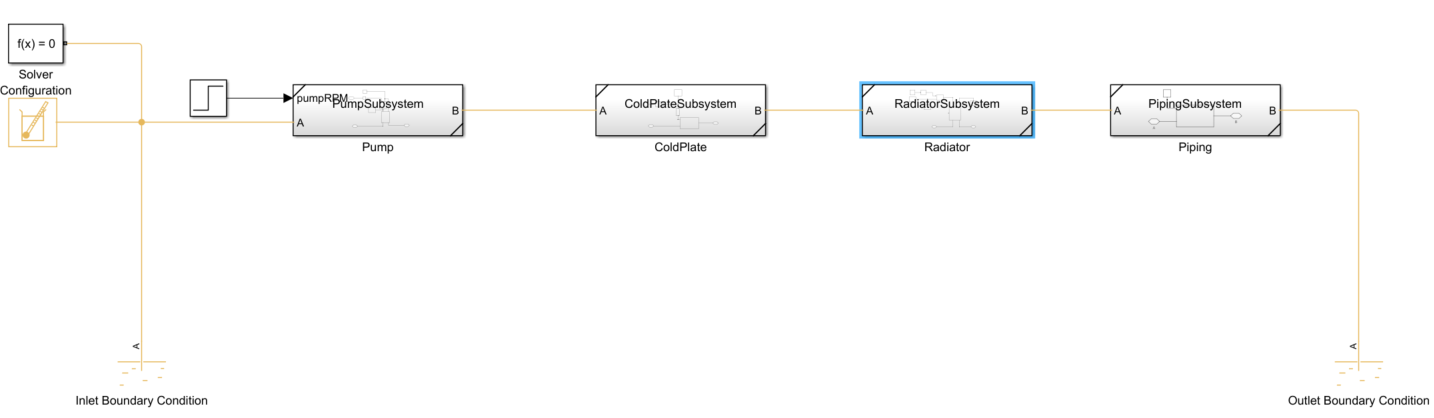

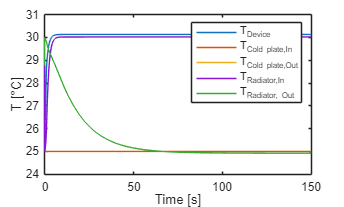

simInp = Simulink.SimulationInput('example_System_Assembly');
simInp = simInp.setModelParameter("StopTime","150");

simOut = sim(simInp);

% Extract results
% Pump
VDot         = simOut.simlog.Pump.Centrifugal_Pump_TL.q_A.series.values('lpm');
% Devide
TDevice      = simOut.simlog.ColdPlate.Device.M.T.series.values('degC');
% Cold plate
TCPInlet     = simOut.simlog.ColdPlate.Pipe_TL.A.T.series.values('degC');
TCPOutlet    = simOut.simlog.ColdPlate.Pipe_TL.B.T.series.values('degC');
pCPInlet     = simOut.simlog.ColdPlate.Pipe_TL.A.p.series.values('bar');
pCPOutlet    = simOut.simlog.ColdPlate.Pipe_TL.B.p.series.values('bar');
% Radiator
TRadiatorInlet     = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.A1.T.series.values('degC');
TRadiatorOutlet    = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.B1.T.series.values('degC');
pRadiatorInlet     = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.A1.p.series.values('bar');
pRadiatorOutlet    = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.B1.p.series.values('bar');
% Piping
pPipingInlet     = simOut.simlog.Piping.Pipe_TL.A.p.series.values('bar');
pPipingOutlet    = simOut.simlog.Piping.Pipe_TL.B.p.series.values('bar');


figure
plot(simOut.tout,[TDevice,TCPInlet,TCPOutlet,TRadiatorInlet,TRadiatorOutlet])
xlabel('Time [s]')
ylabel('T [°C]')
legend('T_{Device}','T_{Cold plate,In}','T_{Cold plate,Out}','T_{Radiator,In}','T_{Radiator, Out}')

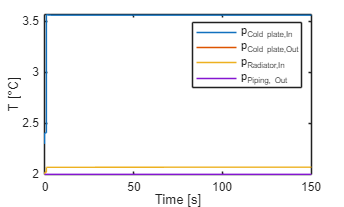


figure
plot(simOut.tout,[pCPInlet,pCPOutlet,pRadiatorInlet,pPipingOutlet])
xlabel('Time [s]')
ylabel('T [°C]')
legend('p_{Cold plate,In}','p_{Cold plate,Out}','p_{Radiator,In}','p_{Piping, Out}')




% Assemble table to display
Measurement         = ["VDot [lpm]";"T_Device [degC]";"T_cp,in [degC]";"T_cp,out [degC]";"T_rad,in [degC]";"T_rad,out [degC]";...
            "p_cp,in [bar]";"p_cp,out [bar]";"p_rad,in [bar]";"p_rad,out [bar]";"p_piping,in [bar]";"p_piping,out [bar]"];

MeasurementValues   = [VDot(end);TDevice(end);TCPInlet(end);TCPOutlet(end);TRadiatorInlet(end);TRadiatorOutlet(end);...
    pCPInlet(end);pCPOutlet(end);pRadiatorInlet(end);pRadiatorOutlet(end);pPipingInlet(end);pPipingOutlet(end)];

outputTable = table(Measurement, MeasurementValues);
disp(outputTable)

        Measurement         MeasurementValues
    ____________________    _________________

    "VDot [lpm]"                 5.7753      
    "T_Device [degC]"            30.133      
    "T_cp,in [degC]"             25.004      
    "T_cp,out [degC]"            30.022      
    "T_rad,in [degC]"            30.022      
    "T_rad,out [degC]"           24.926      
    "p_cp,in [bar]"              3.5602      
    "p_cp,out [bar]"             2.0691      
    "p_rad,in [bar]"             2.0691      
    "p_rad,out [bar]"             2.069      
    "p_piping,in [bar]"           2.069      
    "p_piping,out [bar]"              2      



The table shows the temperatures and pressures staying well within the expected values. 

#### Assembling and testing the cooling loop components - Closed loop

Next, we can close the fluid loop and remove the constant boundary condition (the reservoirs)

open_system("example_System_Assembly_ClosedLoop")   

Notice that in this version, the piping subsystem is replaced by a subsystem which additionally contains a [Gas-Charged Accumulator (TL)](https://www.mathworks.com/help/releases/R2025a/hydro/ref/gaschargedaccumulatortl.html) block. In a closed loop Thermal Liquid network, as fluid temperature changes the density will increase or decrease, an accumulator or tank can provide additional liquid or absorb excess liquid.   

open_system("example_System_Assembly_ClosedLoop/PipingAccumulator")   

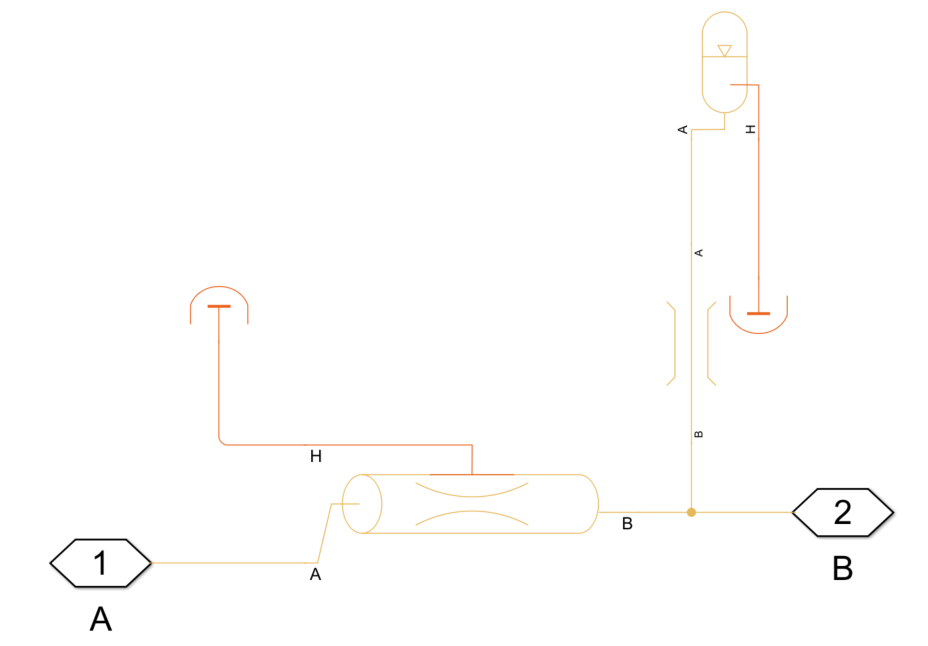

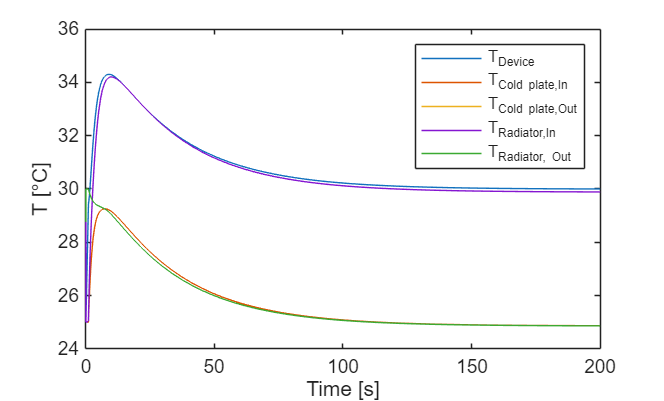

pumpInpSpeed = 2900; % rpm

simInp = Simulink.SimulationInput('example_System_Assembly_ClosedLoop');
simInp = simInp.setModelParameter("StopTime","200");

simOut = sim(simInp);

% Extract results
% Pump
VDot         = simOut.simlog.Pump.Centrifugal_Pump_TL.q_A.series.values('lpm');
% Devide
TDevice      = simOut.simlog.ColdPlate.Device.M.T.series.values('degC');
% Cold plate
TCPInlet     = simOut.simlog.ColdPlate.Pipe_TL.A.T.series.values('degC');
TCPOutlet    = simOut.simlog.ColdPlate.Pipe_TL.B.T.series.values('degC');
pCPInlet     = simOut.simlog.ColdPlate.Pipe_TL.A.p.series.values('bar');
pCPOutlet    = simOut.simlog.ColdPlate.Pipe_TL.B.p.series.values('bar');
% Radiator
TRadiatorInlet     = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.A1.T.series.values('degC');
TRadiatorOutlet    = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.B1.T.series.values('degC');
pRadiatorInlet     = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.A1.p.series.values('bar');
pRadiatorOutlet    = simOut.simlog.Radiator.Heat_Exchanger_TL_MA.B1.p.series.values('bar');
% Piping
pPipingInlet     = simOut.simlog.PipingAccumulator.Pipe_TL.A.p.series.values('bar');
pPipingOutlet    = simOut.simlog.PipingAccumulator.Pipe_TL.B.p.series.values('bar');


figure
plot(simOut.tout,[TDevice,TCPInlet,TCPOutlet,TRadiatorInlet,TRadiatorOutlet])
xlabel('Time [s]')
ylabel('T [°C]')
legend('T_{Device}','T_{Cold plate,In}','T_{Cold plate,Out}','T_{Radiator,In}','T_{Radiator, Out}')

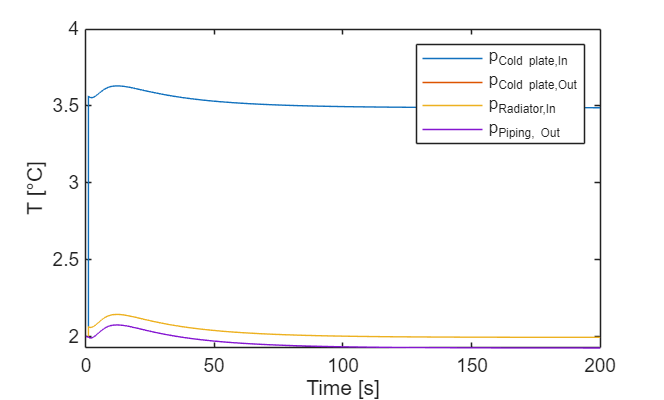


figure
plot(simOut.tout,[pCPInlet,pCPOutlet,pRadiatorInlet,pPipingOutlet])
xlabel('Time [s]')
ylabel('T [°C]')
legend('p_{Cold plate,In}','p_{Cold plate,Out}','p_{Radiator,In}','p_{Piping, Out}')




% Assemble table to display
Measurement         = ["VDot [lpm]";"T_Device [degC]";"T_cp,in [degC]";"T_cp,out [degC]";"T_rad,in [degC]";"T_rad,out [degC]";...
            "p_cp,in [bar]";"p_cp,out [bar]";"p_rad,in [bar]";"p_rad,out [bar]";"p_piping,in [bar]";"p_piping,out [bar]"];

MeasurementValues   = [VDot(end);TDevice(end);TCPInlet(end);TCPOutlet(end);TRadiatorInlet(end);TRadiatorOutlet(end);...
    pCPInlet(end);pCPOutlet(end);pRadiatorInlet(end);pRadiatorOutlet(end);pPipingInlet(end);pPipingOutlet(end)];

outputTable = table(Measurement, MeasurementValues);
disp(outputTable)

        Measurement         MeasurementValues
    ____________________    _________________

    "VDot [lpm]"                 5.7746      
    "T_Device [degC]"                30      
    "T_cp,in [degC]"             24.869      
    "T_cp,out [degC]"            29.888      
    "T_rad,in [degC]"            29.888      
    "T_rad,out [degC]"           24.863      
    "p_cp,in [bar]"              3.4886      
    "p_cp,out [bar]"             1.9973      
    "p_rad,in [bar]"             1.9973      
    "p_rad,out [bar]"            1.9972      
    "p_piping,in [bar]"          1.9972      
    "p_piping,out [bar]"         1.9282      



#### Assembling and testing the cooling loop components - Closed loop

The pump will be controlled to ensure the coldplate outlet temperature stays below the maximum allowed value of 30°C. 

open_system("example_System_Assembly_ClosedLoop_Logic")   

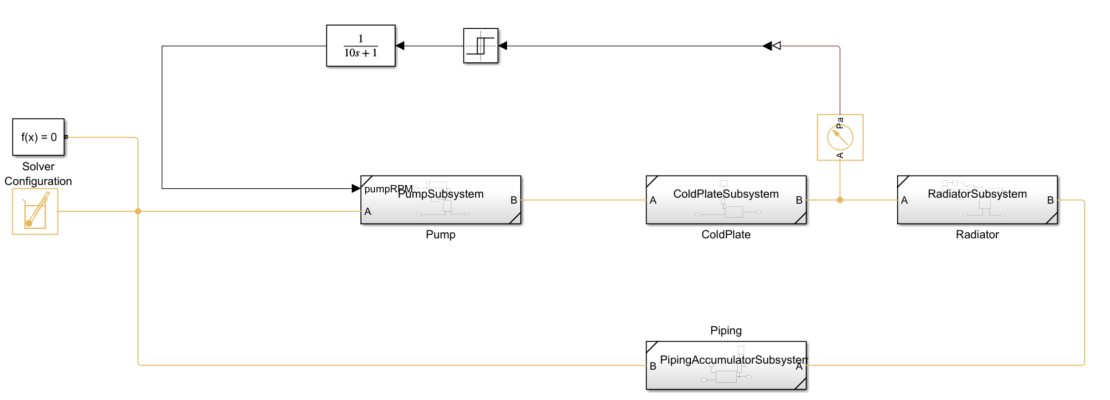

The actual outlet temperature is measured after the cold plate subsystem, the system has a simple logic which turns on the pump at 30°C and runs at 25% reference speed once the temperature hits 25°C. 

**Todo/Ideas:   - Think of some interesting test cases for the overall system, i.e. daily usage profile**

**                       - Still need to add the right thermal mass and properties for the device**